# Complex Step in few steps...for SUPAERO's Students

## Prof Joseph Morlier, ISAE-SUPAERO

The idea is simple and dates from 1967 [1]. Recent work in multidisciplinary optimization [1] has revived the interest of this method (sensitivity calculation). It is in fact a development of Taylor in the case where F (the function to be derived) is analytic with real values.

Let $F(z)$be a function and $x_0$ a real, Taylor development of $F(z)$gives:


$$ F(x_0+ih) = F(x_0)+ihF'(x_0)-h^2F''(x_0)/2!-ih^3F^{(3)}/3!+... $$


...by taking imaginary part (dividing by $h$), it comes:


$$ F'(x_0) = Im(F(x_0+ih))/h + O(h^2) $$


Evaluate $F$ with a complex argument $x_0+ih$, dividing by $h$, gives the derivative $F'(x_0)$ with an order of precision $O(h^2)$. Let's take $h=10^{-8}$ , the approximation error of $F'(x_0)$ is the same than rounded error.

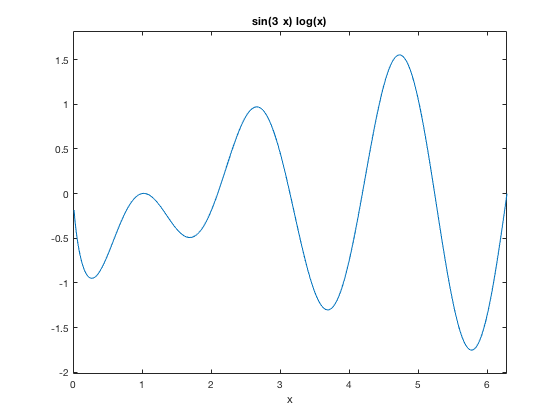

clear all; close all; 
%display
f = @(x) sin(3*x)*log(x);
ezplot(f)

%Symbolic computation (check only
%dfdx = 3*cos(3*x)*log(x) + sin(3*x)/x
syms x
dfdx=diff(f,x)

$$dfdx = 3\,\cos\left(3\,x\right)\,\log\left(x\right)+\frac{\sin\left(3\,x\right)}{x}$$

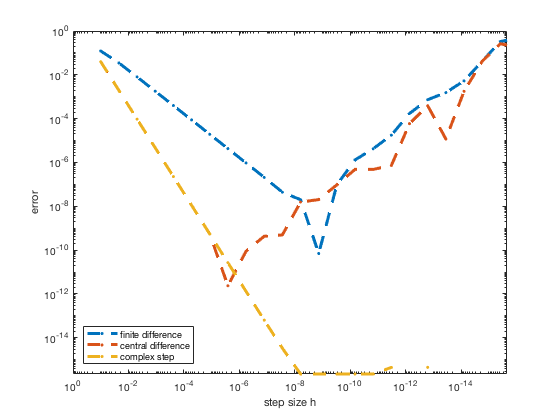

%Derivative evaluation at x=0.7 for 30 values in the range 10^-1 à 10^-20
x = 0.7;
%Loop on step
k=0;
for h = logspace(-1,-20,30)
    k=k+1; 
    H(k)=h;
%analytical derivative
dfdx_a=3*cos(3*x)*log(x) + sin(3*x)/x;
%finite difference
dfdx_fd = (f(x) - f(x-h))/h;
%central difference
dfdx_cd = (f(x+h)-f(x-h))/(2*h);
%complex method
dfdx_cm = imag(f(x+h*i)/h);
%Compute errors
errs(k,1)=abs(dfdx_fd - dfdx_a);
errs(k,2)=abs(dfdx_cd - dfdx_a);
errs(k,3)=abs(dfdx_cm - dfdx_a);
end
%Display
loglog(H,errs,'--.','linewidth', 3)
   axis([eps 1 eps 1])
   set(gca,'xdir','rev')
   legend('finite difference','central difference','complex step','location','southwest')
   xlabel('step size h')
   ylabel('error')

The complex step method is always more accurate than the finite difference method of order 1 (normal!). The method of centered differences (of order 2) begins to diverge more quickly (towards 10 ^ -6) than the method complex step (10 ^ -8)

## References

[1] Lyness, James N., and Moler, Cleve B., Numerical Differentiation of Analytic Functions, *SIAM J. Numerical Analysis 4*, 1967, pp. 202-210.  [epubs.siam.org/doi/abs/10.1137/0704019](http://epubs.siam.org/doi/abs/10.1137/0704019)

[2] Martins, Joaquim R. R. A., A Guide to the Complex-Step Derivative Approximation,  [complex step guide](http://mdolab.engin.umich.edu/content/guide-complex-step-derivative-approximation-0)

Online [https://blogs.mathworks.com/cleve/2013/10/14/complex-step-differentiation/](https://blogs.mathworks.com/cleve/2013/10/14/complex-step-differentiation/)

%